# Fit thermal measurements

This live script is meant to fit the profiles of potential temperature and humidity measured in flight. It computes average profiles from the measurements you provide and fits them with an eight term fouries series. You can play with the coefficients of the fourier series manually as your heart desires.

**Attention: run the script from the root directory (Thermal-Updraft-Model), or the csv files won't be found and the plots will be saved in the wrong folder.**

## Load your .csv files

This loads the data from each .csv file from Hardt (each corresponding to one fly-through) into cell arrays of tables with the measured data. Upwind (UW), downwind (DW) and crosswind (CW) flights each go into a separate array. Additionally, all flights go into the "tables" array. The function import_hardt_thermal can only parse the data Hardt provided. When you start to get new measuments, you will have to create a new function and change the code in the first cell to reflect how your files are named or structured.

Hardt's tables have three colums that we care about: 

- relative distance: the distance to the center of the thermal, normalized such that -1 and 1 are at its outer diameter

- ptemp_diff: the potential temperature difference at each position

- spec_hum_diff: the specific humidity difference at each position

% Clear variables
clear

% load .csv files in the folder into a cell array
files = dir("Raw data\Hardt data\flight_3*.csv"); % Currently only using 3rd flight


tablesUW = cell(length(files), 1);
tablesCW = cell(length(files), 1);
tablesDW = cell(length(files), 1);
tables = cell(length(files), 1);

for i = 1:length(files)
    tables{i} = import_hardt_thermal(fullfile(files(i).folder, files(i).name), [17, Inf]);
    % check if file is crosswind (CW), downwind (DW) or upwind (UW) by checking the file name and store in the corresponding cell array
    if contains(files(i).name, "CW")
        %tablesCW{i} = tables{i};
    elseif contains(files(i).name, "UW")
        tablesUW{i} = tables{i};
    elseif contains(files(i).name, "DW")
        tablesDW{i} = tables{i};
    else
        error("File name does not contain 'CW', 'DW' or 'UW'");
    end
end

% drop empty rows
tables = tables(~cellfun('isempty', tables));
tablesUW = tablesUW(~cellfun('isempty', tablesUW));
tablesCW = tablesCW(~cellfun('isempty', tablesCW));
tablesDW = tablesDW(~cellfun('isempty', tablesDW));

## Average profiles

Now we obtain the average profiles of ptemp and spec_hum. The profiles are truncated to -4 and 4 relative distance.

% compute average values for each flight type

[ptemp_DW_avg, spec_hum_DW_avg, rel_distDW] = average_hardt(tablesDW);
%[ptemp_CW_avg, spec_hum_CW_avg, rel_distCW] = average_hardt(tablesCW);
[ptemp_UW_avg, spec_hum_UW_avg, rel_distUW] = average_hardt(tablesUW);
[ptemp_avg, spec_hum_avg, rel_dist] = average_hardt(tables);

## Fit profiles

Fit the profiles to a fourier series with eight terms.

Note: from this point on, everything that concerns crosswind fly-throughs has been commented out, since the third flight does not have any.

ptemp_DW_fit = fit(rel_distDW', ptemp_DW_avg', 'fourier8');
spec_hum_DW_fit = fit(rel_distDW', spec_hum_DW_avg', 'fourier8');

%ptemp_CW_fit = fit(rel_distCW', ptemp_CW_avg', 'fourier8');
%spec_hum_CW_fit = fit(rel_distCW', spec_hum_CW_avg', 'fourier8');

ptemp_UW_fit = fit(rel_distUW', ptemp_UW_avg', 'fourier8');
spec_hum_UW_fit = fit(rel_distUW', spec_hum_UW_avg', 'fourier8');

[ptemp_fit, gof_ptemp] = fit(rel_dist', ptemp_avg', 'fourier8');
disp(gof_ptemp)

           sse: 81.1891
       rsquare: 0.7744
           dfe: 79982
    adjrsquare: 0.7744
          rmse: 0.0319



[spec_hum_fit, gof_hum] = fit(rel_dist', spec_hum_avg', 'fourier8');
disp(gof_hum)

           sse: 388.4301
       rsquare: 0.6490
           dfe: 79982
    adjrsquare: 0.6489
          rmse: 0.0697



#### Plot the profiles and their fits

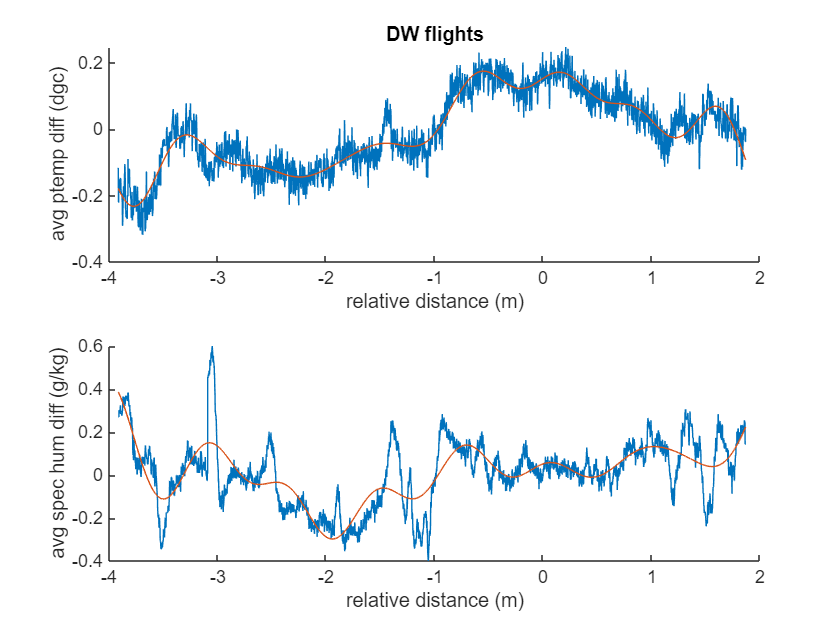

figure
subplot(2,1,1)
hold on
plot(rel_distDW, ptemp_DW_avg)
plot(rel_distDW, ptemp_DW_fit(rel_distDW))
xlabel('relative distance (m)')
ylabel('avg ptemp diff (dgc)')
title('DW flights')
subplot(2,1,2)
hold on
plot(rel_distDW, spec_hum_DW_avg)
plot(rel_distDW, spec_hum_DW_fit(rel_distDW))
xlabel('relative distance (m)')
ylabel('avg spec hum diff (g/kg)')

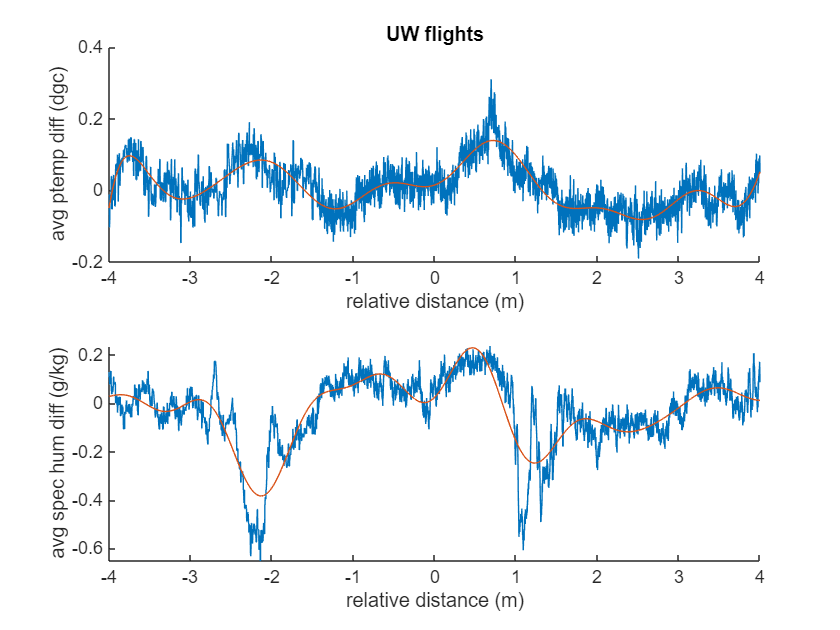


figure
subplot(2,1,1)
hold on
plot(rel_distUW, ptemp_UW_avg)
plot(rel_distUW, ptemp_UW_fit(rel_distUW))
xlabel('relative distance (m)')
ylabel('avg ptemp diff (dgc)')
title('UW flights')
subplot(2,1,2)
hold on
plot(rel_distUW, spec_hum_UW_avg)
plot(rel_distUW, spec_hum_UW_fit(rel_distUW))
xlabel('relative distance (m)')
ylabel('avg spec hum diff (g/kg)')

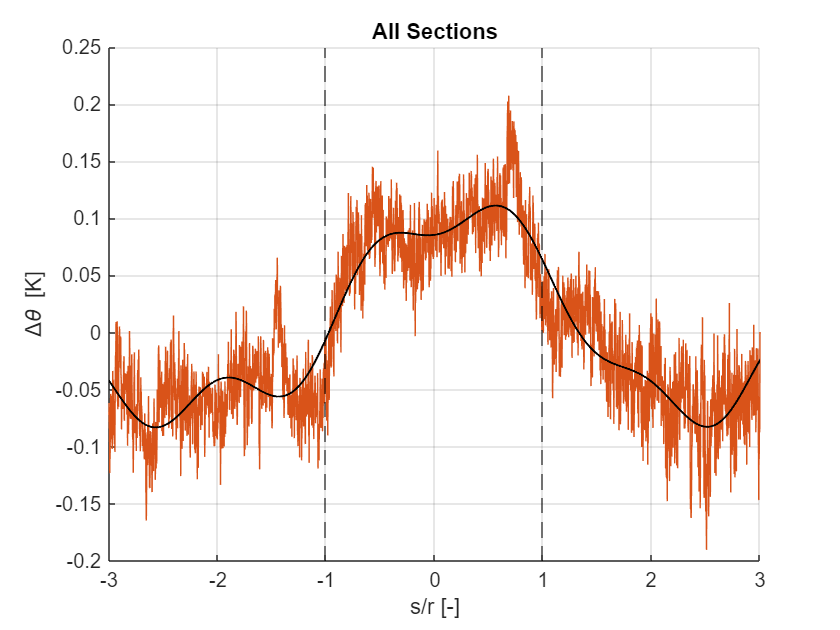


% figure
% subplot(2,1,1)
% hold on
% plot(rel_distCW, ptemp_CW_avg)
%plot(rel_distCW, ptemp_CW_fit(rel_distCW))
% xlabel('relative distance (m)')
% ylabel('avg ptemp diff (dgc)')
% title('CW flights')
% subplot(2,1,2)
% hold on
% plot(rel_distCW, spec_hum_CW_avg)
% plot(rel_distCW, spec_hum_CW_fit(rel_distCW))
% xlabel('relative distance (m)')
% ylabel('avg spec hum diff (g/kg)')

figure
grid('on')
xlim([-3 3])
xline(-1, 'k--', 'LineWidth', 0.5);
xline(1, 'k--', 'LineWidth', 0.5);
hold on
xlabel('s/r [-]')
ylabel('\Delta\theta [K]')
title('All Sections')
plot(rel_dist, ptemp_avg,'Color','#D95319')
plot(rel_dist, ptemp_fit(rel_dist),'Color','#000000','LineWidth',1)

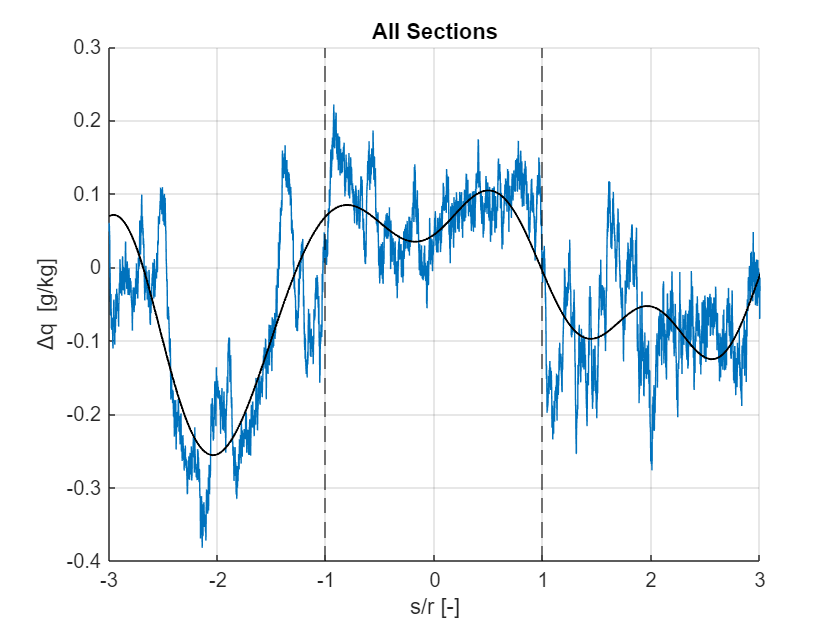

%saveas(gcf,'Images/Thermal model/avg-all3-ptemp-fit','png')

figure
grid('on')
xlim([-3 3])
xline(-1, 'k--', 'LineWidth', 0.5);
xline(1, 'k--', 'LineWidth', 0.5);
hold on
xlabel('s/r [-]')
ylabel('\Deltaq [g/kg]')
plot(rel_dist, spec_hum_avg,'Color','#0072BD')
plot(rel_dist, spec_hum_fit(rel_dist),'Color','#000000','LineWidth',1)
title('All Sections')

%saveas(gcf,'Images/Thermal model/avg-all3-hum-fit','png')

## Save coefficients to workspace

This saves the fourier coefficients to the Processed data folder. Updraft objects load these coefficients when they are initialized.

%coeff_cw = [coeffvalues(ptemp_CW_fit);coeffvalues(spec_hum_CW_fit)];
coeff_uw = [coeffvalues(ptemp_fit);coeffvalues(spec_hum_fit)];
% The same coefficients are used for the crosswind direction since flight 3
% did not have crosswind fly-throughs:
coeff_cw = [coeffvalues(ptemp_fit);coeffvalues(spec_hum_fit)];
save("Processed Data/coeff_cw.mat","coeff_cw");
save("Processed Data/coeff_uw.mat","coeff_uw");

## Plots for thesis

### Examplary cross-sections

#### Temperature

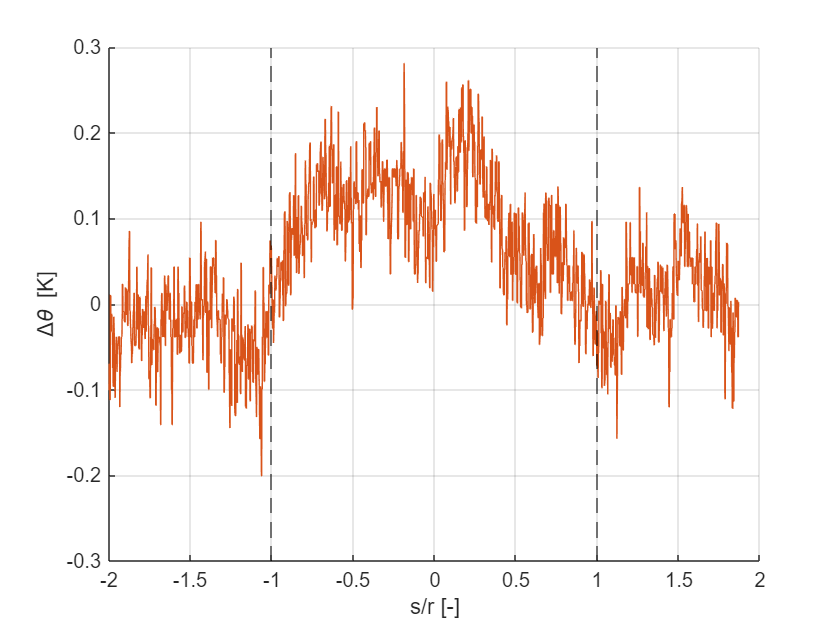

figure
flight = 1;
xlabel('s/r [-]')
ylabel('\Delta\theta [K]')
xlim([-2. 2])
xline(-1, 'k--', 'LineWidth', 0.5);
xline(1, 'k--', 'LineWidth', 0.5);
hold on
plot(tablesDW{flight,1}.relative_distance_m,tablesDW{flight,1}.ptemp_diff_dgc,'Color','#D95319')
grid('on')

#### Humidity

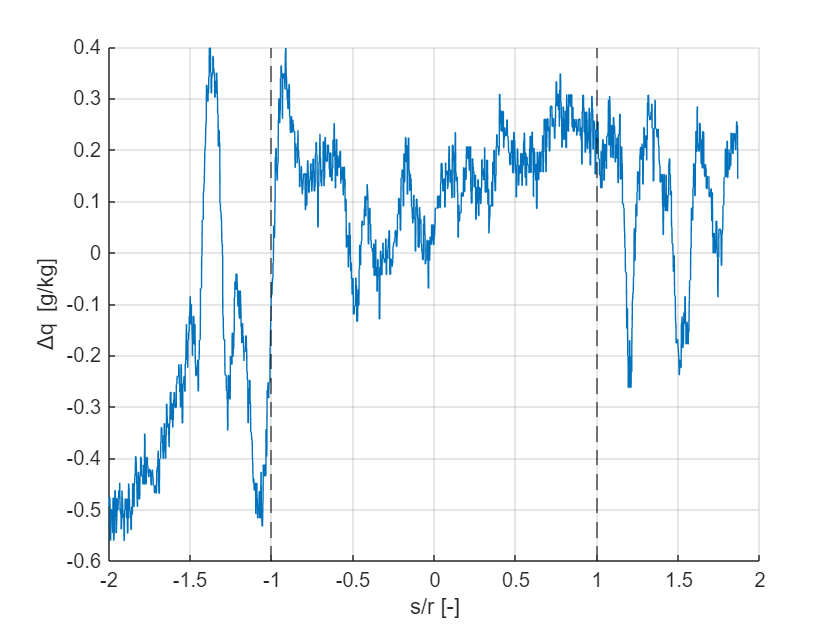

figure
ylabel('\Deltaq [g/kg]')
xlabel('s/r [-]')
grid('on')
xlim([-2. 2])
xline(-1, 'k--', 'LineWidth', 0.5);
xline(1, 'k--', 'LineWidth', 0.5);
hold on
plot(tablesDW{flight,1}.relative_distance_m,tablesDW{flight,1}.spec_hum_diff_gkg,'Color','#0072BD')

### Averages of CW, DW and UW

#### Temperature

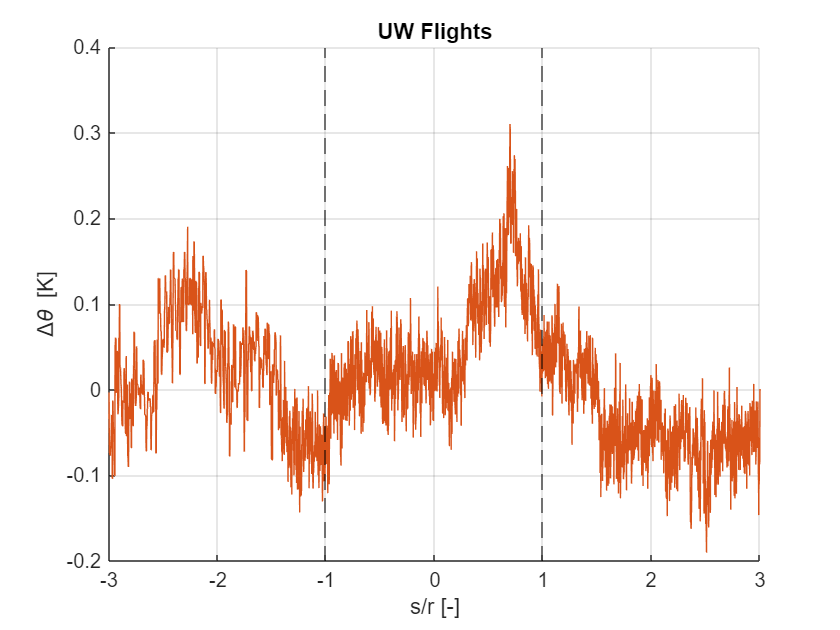

figure
grid('on')
xlabel('s/r [-]')
ylabel('\Delta\theta [K]')
xlim([-3 3])
xline(-1, 'k--', 'LineWidth', 0.5);
xline(1, 'k--', 'LineWidth', 0.5);
hold on
plot(rel_distUW, ptemp_UW_avg,'Color','#D95319')
title('UW Flights')

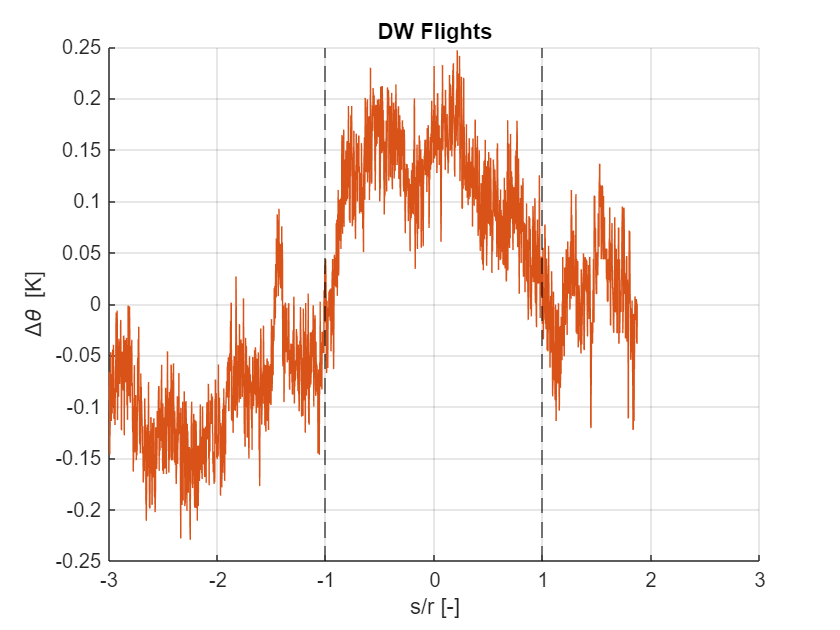

%saveas(gcf,'Images/Thermal model/avg-uw-ptemp','png')

figure
grid('on')
xlim([-3 3])
xline(-1, 'k--', 'LineWidth', 0.5);
xline(1, 'k--', 'LineWidth', 0.5);
hold on
plot(rel_distDW, ptemp_DW_avg,'Color','#D95319')
xlabel('s/r [-]')
ylabel('\Delta\theta [K]')
title('DW Flights')

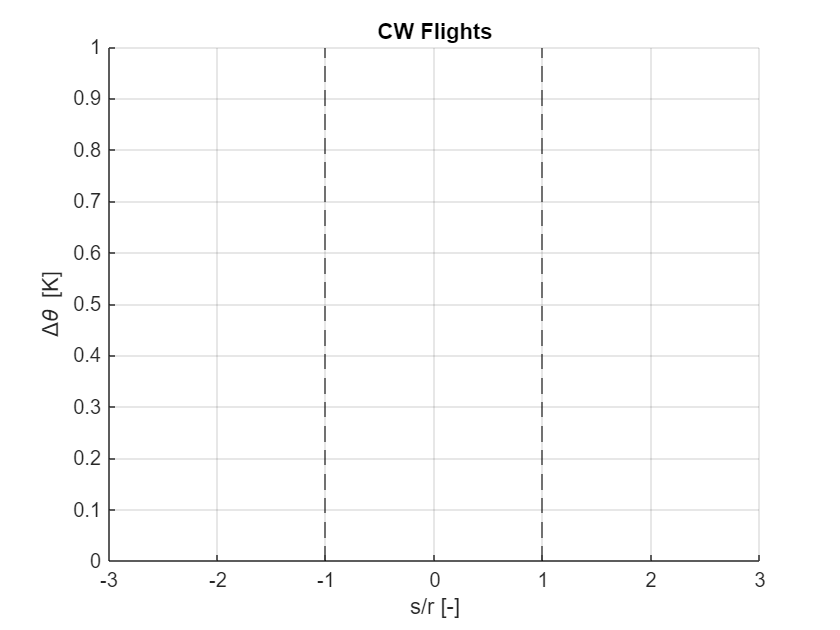

%saveas(gcf,'Images/Thermal model/avg-dw-ptemp','png')

figure
grid('on')
xlim([-3 3])
xline(-1, 'k--', 'LineWidth', 0.5);
xline(1, 'k--', 'LineWidth', 0.5);
hold on
xlabel('s/r [-]')
ylabel('\Delta\theta [K]')
%plot(rel_distCW, ptemp_CW_avg,'Color','#D95319')
title('CW Flights')

%saveas(gcf,'Images/Thermal model/avg-cw-ptemp','png')

#### Humidity

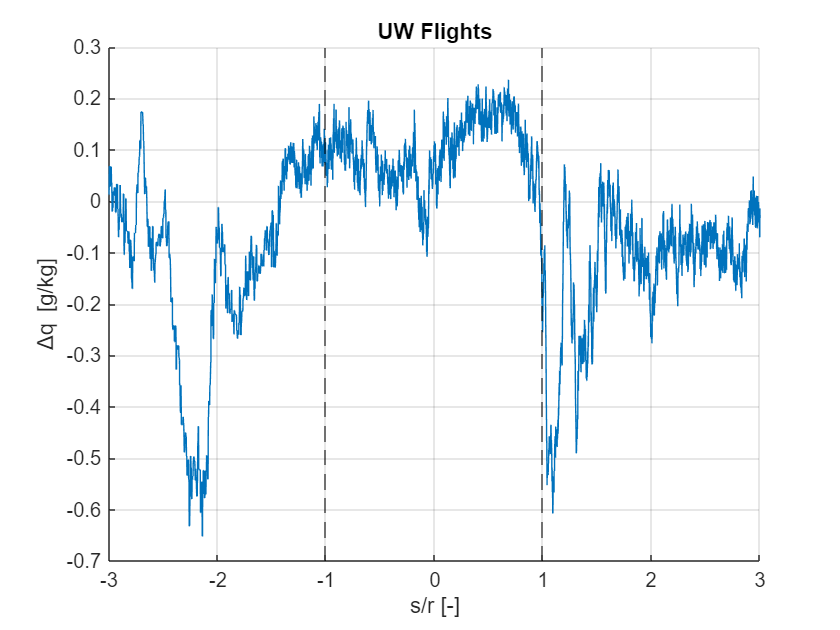

figure
grid('on')
xlabel('s/r [-]')
ylabel('\Deltaq [g/kg]')
xlim([-3 3])
xline(-1, 'k--', 'LineWidth', 0.5);
xline(1, 'k--', 'LineWidth', 0.5);
hold on
plot(rel_distUW, spec_hum_UW_avg,'Color','#0072BD')
title('UW Flights')

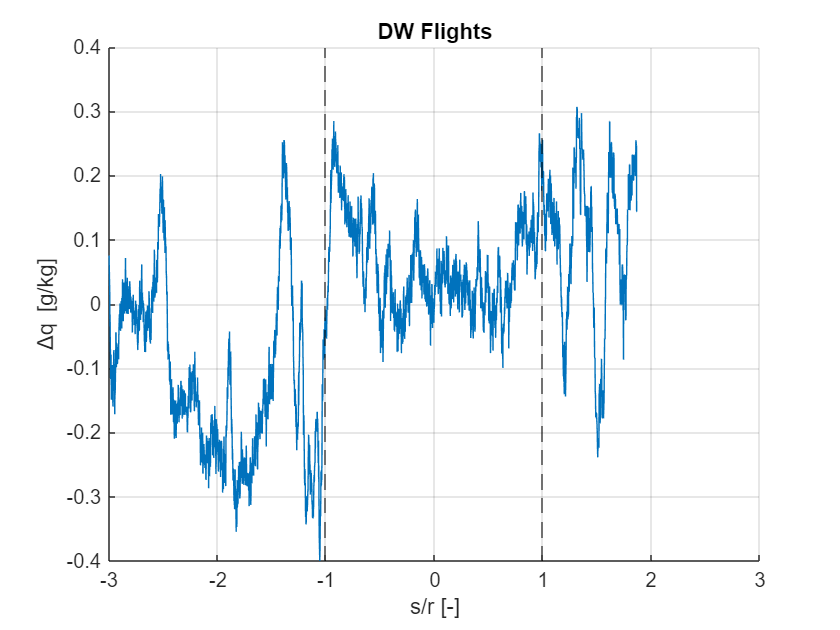

%saveas(gcf,'Images/Thermal model/avg-uw-hum','png')

figure
grid('on')
xlim([-3 3])
xline(-1, 'k--', 'LineWidth', 0.5);
xline(1, 'k--', 'LineWidth', 0.5);
hold on
plot(rel_distDW, spec_hum_DW_avg,'Color','#0072BD')
xlabel('s/r [-]')
ylabel('\Deltaq [g/kg]')
title('DW Flights')

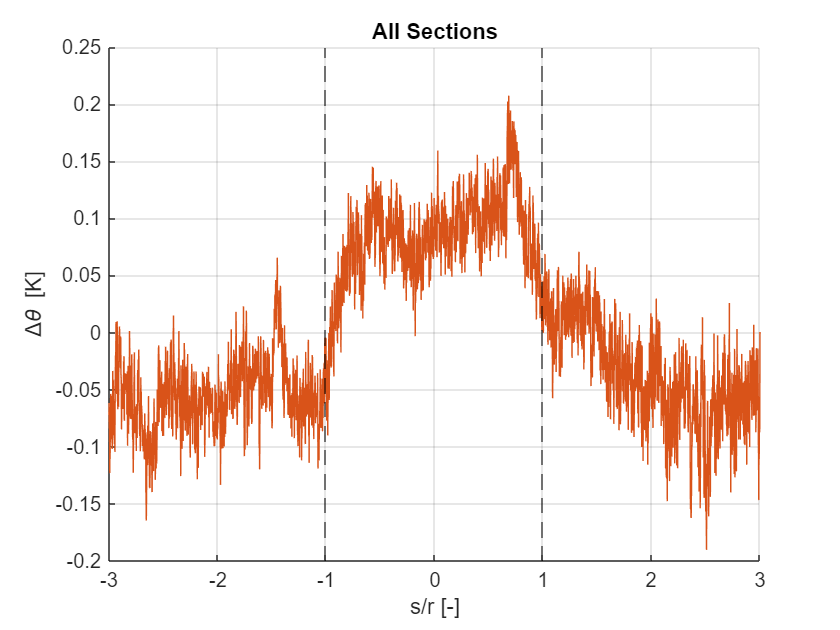

%saveas(gcf,'Images/Thermal model/avg-dw-hum','png')

% figure
% grid('on')
% xlim([-3 3])
% xline(-1, 'k--', 'LineWidth', 0.5);
% xline(1, 'k--', 'LineWidth', 0.5);
% hold on
% xlabel('s/r [-]')
% ylabel('\Deltaq [g/kg]')
% plot(rel_distCW, spec_hum_CW_avg,'Color','#0072BD')
% title('CW Flights')
% saveas(gcf,'avg-cw-hum','png')

figure
grid('on')
xlim([-3 3])
xline(-1, 'k--', 'LineWidth', 0.5);
xline(1, 'k--', 'LineWidth', 0.5);
hold on
xlabel('s/r [-]')
ylabel('\Delta\theta [K]')
plot(rel_dist, ptemp_avg,'Color','#D95319')
title('All Sections')

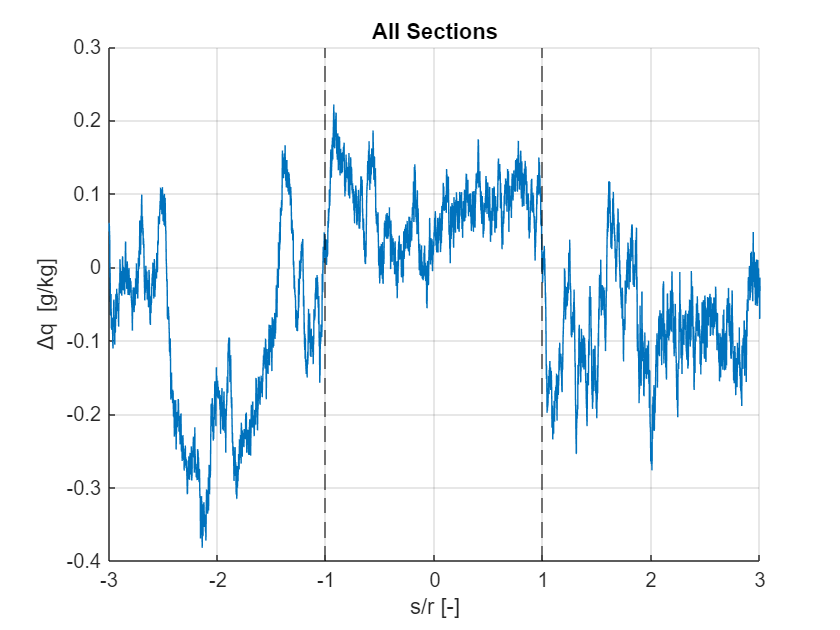

%saveas(gcf,'Images/Thermal model/avg-all3-ptemp','png')

figure
grid('on')
xlim([-3 3])
xline(-1, 'k--', 'LineWidth', 0.5);
xline(1, 'k--', 'LineWidth', 0.5);
hold on
xlabel('s/r [-]')
ylabel('\Deltaq [g/kg]')
plot(rel_dist, spec_hum_avg,'Color','#0072BD')
title('All Sections')

%saveas(gcf,'Images/Thermal model/avg-all3-hum','png')

## Change fit coefficients

If you wish to change the coeeficients of the fit manually, you can test out new values here.

% Original values
fit = ptemp_fit;
data = ptemp_avg;
coeff = coeffvalues(fit);
coeff_names = coeffnames(fit);
f = fittype(fit);

% New fourier series coefficients <- Change here!
a0 = 0.1922;
a1 = -0.3541;
b1 = 0.0237;
a2 = 0.3984;
b2 = -0.01521;
a3 = -0.2569;
b3 = 0.03833;
a4 = 0.2108;
b4 = -0.02081;
a5 = -0.1391;
b5 = 0.02256;
a6 = 0.07744;
b6 = -0.02059;
a7 = -0.03413;
b7 = 0.006951;
a8 = -0.009141;
b8 = -0.005133;
w = 0.6085;

% Create new fit
new_fit = cfit(f,a0,a1,b1,a2,b2,a3,b3,a4,b4,a5,b5,a6,b6,a7,b7,a8,b8,w);
disp(f);

     General model Fourier8:
     f(a0,a1,b1,a2,b2,...,a8,b8,w,x) = 
               a0 + a1*cos(x*w) + b1*sin(x*w) + 
               a2*cos(2*x*w) + b2*sin(2*x*w) + a3*cos(3*x*w) + b3*sin(3*x*w) + 
               a4*cos(4*x*w) + b4*sin(4*x*w) + a5*cos(5*x*w) + b5*sin(5*x*w) + 
               a6*cos(6*x*w) + b6*sin(6*x*w) + a7*cos(7*x*w) + b7*sin(7*x*w) + 
               a8*cos(8*x*w) + b8*sin(8*x*w)


fprintf('Original coefficients: %s\nNew coefficients:      %s', num2str(coeff), num2str([a0,a1,b1,a2,b2,w]))

Original coefficients: 0.19223    -0.35406    0.023696     0.39843    -0.01521    -0.25691    0.038326     0.21077   -0.020809    -0.13907    0.022564    0.077441   -0.020591   -0.034128   0.0069509  -0.0091409  -0.0051326     0.60847
New coefficients:      0.1922     -0.3541      0.0237      0.3984    -0.01521      0.6085

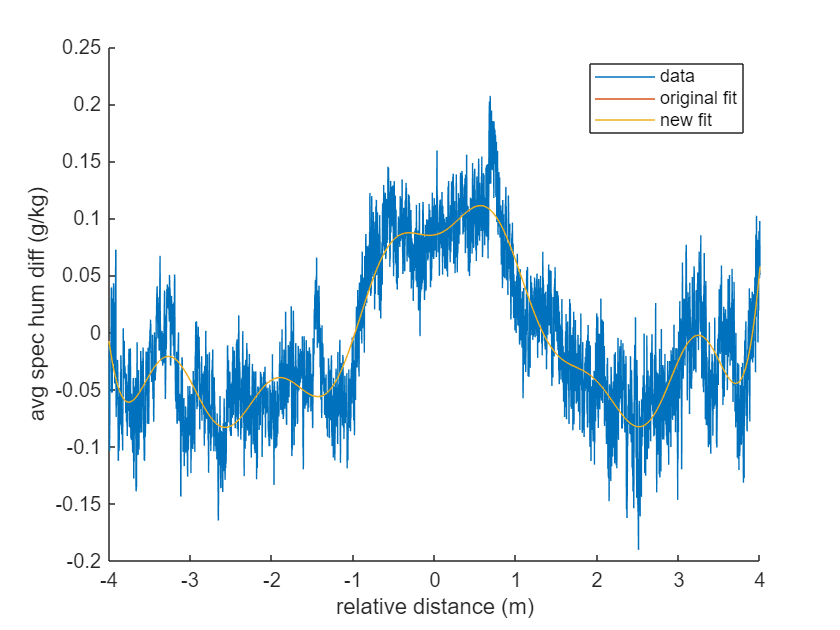

% Plot
figure
hold on
plot(rel_dist, data, DisplayName='data')
plot(rel_dist, fit(rel_dist), DisplayName='original fit')
plot(rel_dist, new_fit(rel_dist),DisplayName='new fit')
xlabel('relative distance (m)')
ylabel('avg spec hum diff (g/kg)')
legend()